%EE451 Homework 7
% Lisa Jacklin
% 11/1/2023

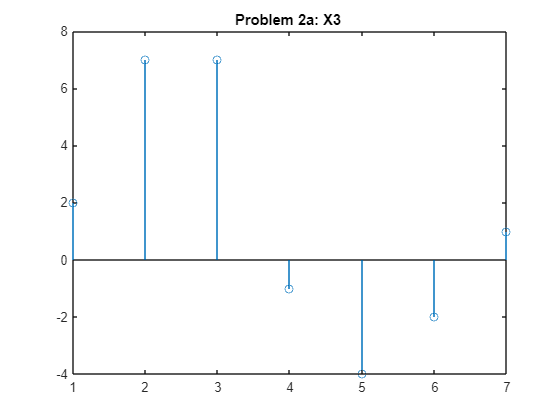


%Problem 2
%part a: convolution of x1n and x2n
x1n = [1 3 2 -1];
x2n = [2 1 0 -1];

X3 = conv(x1n, x2n);
%now that X3 has been determined we need to plot it!
stem(X3);
title("Problem 2a: X3 ");

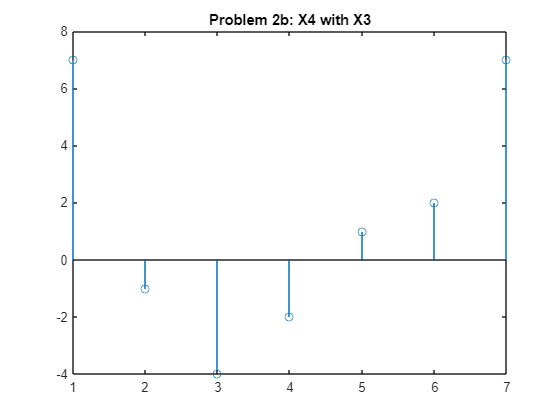


%part b: circular convolution of 5 of x1n and x2n
%this has to be determined using only x3 to sketch and determine the
%circular convolution....

%we are given that the circular shift is 5 so
X4 = circshift(X3,5);

%now we can graph this
stem(X4);
title("Problem 2b: X4 with X3");

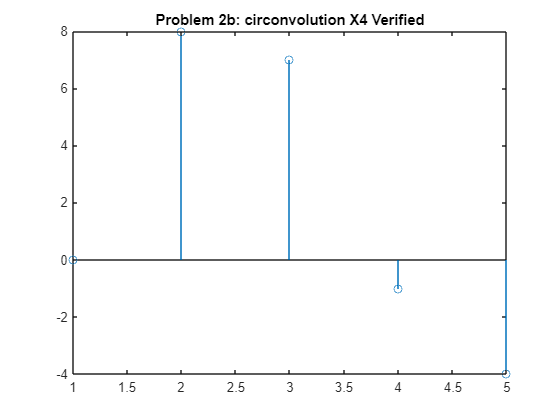


%to double check that this is correct, I will use the function
%circconvolution created in class which takes two signals, x1 and x2 as well
%as the shift to compare and verify that X4 above is correct.

X4b = circconvolution(x1n, x2n, 5);
stem(X4b);
title("Problem 2b: circonvolution X4 Verified");


%note that although X4b only displays 5 samples, these are the same
%signals.


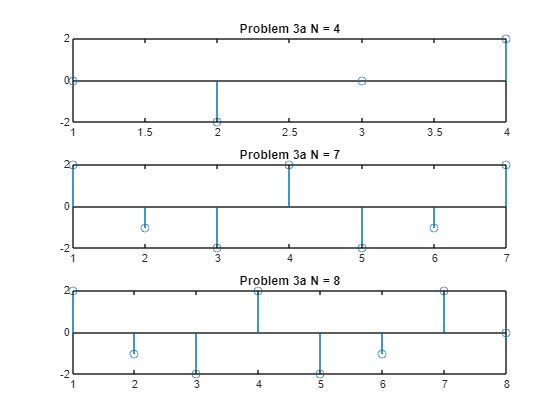

%Problem 3
%given the following sequences of x1n and x2n, do the following....

x1n4 = [2 1 1 2];
x2n4 = [1 -1 -1 1];

%part a: compute and plot the circular conv. x1n4(N)x2n4 for N = 4, N = 7,
%and N = 8.

%for N = 4
Xa1 = circconvolution(x1n4, x2n4, 4); 
subplot(3, 1, 1);
stem(Xa1);
title("Problem 3a N = 4")

%for N = 7
Xa2 = circconvolution(x1n4, x2n4, 7);
subplot(3,1, 2);
stem(Xa2);
title("Problem 3a N = 7");

% for N = 8
Xa3 = circconvolution(x1n4, x2n4, 8);
subplot(3,1,3);
stem(Xa3);
title("Problem 3a N = 8");

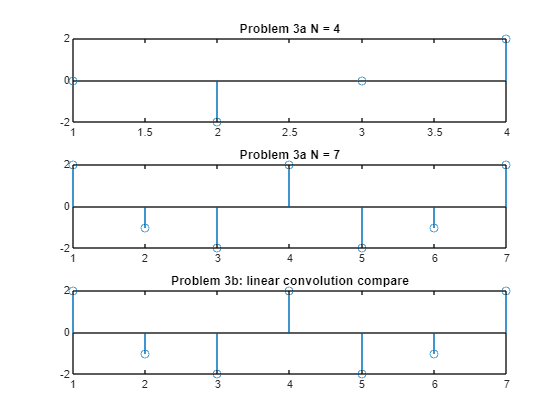


%Part b: compute and plot the linear convolution x1n * x2n

X3b = conv(x1n4, x2n4);
stem(X3b);%this plot is displayed in place of N = 8, look at how it compares to N = 7
title("Problem 3b: linear convolution compare");

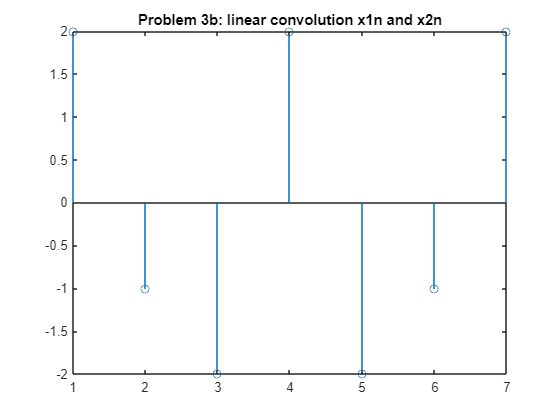

figure; stem(X3b); %and for clarity, how it appears on its own.
title("Problem 3b: linear convolution x1n and x2n");

%Problem 4
%first, I need to generate xn which is a random uniformly distributed
%function that runs between [-1 1] for 0 <=n<= 10^7 (or 10^6 or higher
%depending on processor...Will note on this as I continue through
%programming)

% Define the number of samples. Note that for quick compilations, I am
% sticking with N = 10^7, but my desktop can run up to 10^9 and laptop up
% to 10^12 although with a very unhappy matlab...
N = 10^7;
% Generate random numbers in the range [0, 1] since rand does not generate
% negative numbers.
random_numbers = rand(N, 1);
% Scale to the range [-1, 1] so we can achieve what we are looking for!
x4n = 2 * random_numbers - 1;
% Now, x4n contains N random values in the range [-1, 1].

%now we need to include hn
n = 0:1:100;
hn = sin(0.4*4*pi*n);

%now, setting up to take 5 samples for each of the parts of problem 4 and
%averaging.

%part a: matlab conv function between x and h
Reps = 5; %5 samples

tic;%starts the timer
    for i = 1:Reps
        tstart = tic; %sets tstart as the timer value
        
        X4a = conv(x4n, hn); %convolution being tested

       telapsed = toc(tstart); %end the timer and calculate the time
       disp("Time Results:" + telapsed+ " sec"); %display each of the 5 tests
    end

Time Results:0.027161 sec
Time Results:0.023955 sec
Time Results:0.025143 sec
Time Results:0.024646 sec
Time Results:0.024084 sec



    averageTimeA = toc/Reps;
    disp("Average Time of 5 generations: " + averageTimeA + " sec");

Average Time of 5 generations: 0.02643 sec



    %part b: overlap and save (developed in lab...) along with FFT of block
    %size 1024.

    N4b = 1024; %the given block size

    %note that Reps is the same for all of problem 4
    tic;%starts the timer
    for i = 1:Reps
        tstartb = tic; %sets tstart as the timer value
        %need to check overlap and save for accuracy
        X4b = overlapsave(x4n, hn, N4b); %overlap and save being tested

       telapsedb = toc(tstartb); %end the timer and calculate the time
       disp("Time Results:" + telapsedb+ " sec"); %display each of the 5 tests
    end

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

Error in overlapsave (line 14)
x = [zeros(1,M1), x, zeros(1, N-1)];


    averageTimeA = toc/Reps;
    disp("Average Time of 5 generations: " + averageTimeA + " sec");


     %part b: overlap and save (developed in lab...) along with FFT of block
    %size 4096.

    N4c = 4096; %the given block size

    %note that Reps is the same for all of problem 4
    tic;%starts the timer
    for i = 1:Reps
        tstartc = tic; %sets tstart as the timer value
        
        X4c = overlapsave(x4n, hn, N4c); %overlap and save being tested

       telapsedc = toc(tstartc); %end the timer and calculate the time
       disp("Time Results:" + telapsedc+ " sec"); %display each of the 5 tests
    end

    averageTimeA = toc/Reps;
    disp("Average Time of 5 generations: " + averageTimeA + " sec");
